# GReS - Input Files

## Introduction

Input files are the preferred (and sometimes the only) way to construct objects of a GReS model. 

We expect most of the users to spend most of their time in GReS in modifying input files, rather than writing Matlab code. Therefore, this tutorial provides a detailed description of all the input file that are needed in GReS to run a single-domain simulation. 

dirpath = fullfile(gres_root,'Tutorial','inputFiles');
cd(dirpath)

## XML format

All the input files in GReS are written in .xml file format. This format is user friendly, and the block structure is well suited for a modular multi-physics code. Matlab provides the high level functions [readstruct](https://it.mathworks.com/help/matlab/ref/readstruct.html) (and writestruct) to read (and write) .xml file to (and from) structure objects. 

An helper function [getXMLData()](matlab:open('..\..\Utilities\xmlInput\getXMLData.m')) is largely used in GReS to cast input into a Matlab variable of the correct type.

help getXMLData

  getXMLData  Retrieve and convert a parameter from an XML-derived structure
 
    data = getXMLData(fieldStruct, defaultValue, dataName)
 
    Retrieves the value associated with the XML field `dataName` within the
    structure `fieldStruct`. If the field is missing or explicitly set to
    "Default", the value `defaultValue` is returned. Otherwise, the raw XML
    value is converted to an appropriate MATLAB type using getXMLValue.
 
    Inputs:
      fieldStruct   - Matlab Struct containing parsed XML fields.
      defaultValue  - Fallback value used when the field is absent or marked
                      as default.
      dataName      - Name of the field to extract from the struct.
 
    Output:
      data          - Parsed parameter value. Raises an error if the resulting
                      value is empty.
 
    See also: getXMLValue



In what follows, we will describe the available XML blocks to instanciate all GReS classes. 

## Simulation parameters

This XML block defines the simulation parameters, including time-stepping control and solver settings. The `<simParam>` element organizes all global numerical parameters for the simulation.

The `<Time>` element specifies the time stepping controls:

- `Start`: initial simulation time

- `End`: final simulation time

- `DtInit`: initial time step size

- `DtMax`: maximum allowable time step

- `DtMin`: minimum allowable time step

- `incrementFactor`: factor used to increase the time step during the simulation

The `<Solver>` element specifies basic iterative solver parameters:

- `RelativeTolerance`: relative convergence tolerance for rhs in iterative solvers w.r.t initial rhs norm;

- `AbsoluteTolerance`: absolute convergence tolerance for rhs in iterative solvers

- `MaxNLIteration`: maximum number of Newton iterations before performing backstep.

## Materials

The materials XML file defines material properties for a simulation. All materials are listed inside the `<Materials>` root element. Each material block describes the physical parameters assigned to a set of cells in the computational domain. Inside the `<Materials>` block, the user can specify one or more Solid materials and Fluid.

### <Solid>

Solid materials are defined with a `<Solid>` block. The attribute:

- `cellTags`: a comma-separated list of valid cellTags of the cells to which material properties are assigned. 

Multiple `<Solid>` blocks may be defined, each with different cellTags and property sets.

Each <Solid> contains two sub-blocks:

`<Constitutive>`

   Defines the mechanical constitutive model. For instance, for an elastic material

The name of the consitutive model shoud match one of the available constitutive laws in the Materials folder.

`<PorousRock>`

   Defines hydrogeological properties of the porous media:

   - `porosity`: Void fraction of the solid.

   - specificWeight: Specific weight of the rock.

   - `permeability`: Components of the intrinsic permeability tensor. The user can pass a scalar (isotropic permeability), a 3 independent entries (diagonal permability tensor) or 6 entries (symmetric tensor in voigt notation)

Example:

### <Fluid>

Fluid properties are defined using a `<Fluid>` block outside the solids. Supported attributes:

- `compressibility`: Fluid compressibility.

- specificWeight: Specific weight of the fluid.

- `dynamicViscosity`: Dynamic viscosity of the fluid.

Example:

For now, GReS allow the definition one only fluid phase, which is assigned by default to all the cells where a flow model is active.

## Boundary Conditions

Boundary conditions are constructed as

The .xml file must contain a `<BoundaryConditions> `root. Each boundary condition is specified by a` <BC>` block, which describes its name, type, entity type, and associated physical variable. A `<BC> `contains two optional sub-blocks: 

- <BCentities>, which defines where the boundary condition applies

- <BCevent>, which defines how the boundary value evolves with time.

The `<BC>` element supports the following attributes:

- `name`: Identifier of the boundary condition.

- `type`: Type of constraint (e.g., Dirichlet, Neumann). 

- `entityType`: Category of entity affected (e.g., SurfBC, VolumeForce, NodeBC).

- `variable`: The field on which the BC acts (e.g., displacements, pressure).  *Important: it is the user's responsibility to define **variable names that are actually registered from a solver**. GReS does not check this when the Boundaries object is created.*

### <BCentities>

The `<BCentities>` block specifies the constrained entities. Supported attributes:

- `bcListFile`: Path to a file containing a list of entity IDs.

- `surfaceTags`: Tags of surfaces to which the constraint applies.

- `bcList`: Inline list of entity IDs.

For multicomponent variables (e.g., displacements), when using bcList or surfaceTags, the user must specify one or more constrained components:

`components` = "x", "y,z", or "x,y,z".

Examples:

### <BCevent>

The `<BCevent>` block defines the time evolution of the boundary condition. Required attributes:

- time: A scalar value indicating when the event occurs, or a function handle defining a time-dependent scalar multiplier of the given values.

- value: A scalar value (constant across all DOFs), a path to a file of per-DOF values, or a function handle depending on spatial coordinates (x, y, z).

Multiple` <BCevent>` entries create time-varying boundary conditions. GReS computes the Boundary condition values performing linear interpolation between the available `<BCevents>`.

Example: Dirichlet displacement constraint using a list from file

Example: Time-dependent flux on a single cell

Example: Fully fixed displacements on the bottom surface of a domain

## Outputs

This `<Output> `XML block configures the output settings for the simulation. All options are defined within a single `<Output>` element, which controls how results are written, when they are recorded, and whether history data is stored.

The `printTimes` field defines the time instants at which outputs are generated. It can be a comma-separated list of values placed directly in the XML, as shown above, or a path to a separate file containing one time per line. If the printTime falls within a time step of the simulation, GReS linearly interpolates the solution obtained before and after the time step. 

The `outputFile` attribute specifies the base name of the visualization file produced for tools such as ParaView. Notice that in this case, the results are conveniently store in a folder called `Outputs, `whichis created from scratch if not yet existing in the current folder. If this field is omitted, no visualization output is generated, allowing simulations to run without producing graphical files. 

The `matFileName` attribute defines the name of a MATLAB .mat file used to store history quantities, i.e time series of selected variables collected during the simulation.

The `saveHistory` flag determines whether history data is saved. A value of "0" disables history output, while "1" activates it, causing the solver to write the requested quantities into the mat file at specified times.

For the .xml example provided above, the Outputs folder will look like

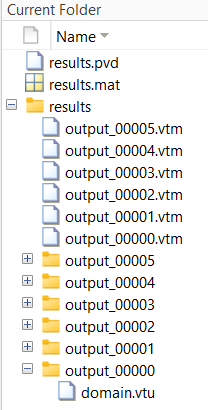

You will find:

- a .`pvd` file that can be opened in ParaView, and a folder (with the same name) collecting subfolders for each of the printTimes (5 in this case). Each subfolder contains a .vtk file, which is named `domain` by default. 

- a `.mat `file, containing a struct named `output `(see figure below)`. `The field of the structures are inserted and populated by the physicsSolver of the simulation.

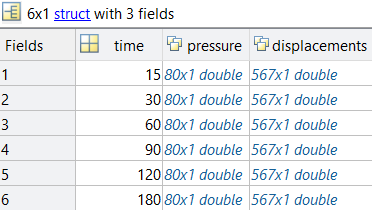

## Discretizer

A fundamental object in GReS is the Discretizer. This is basically a wrapper of all the input seen so far, that are common to single domain:

- A grid (mesh,elements and faces)

- Materials

- Boundary conditions

- Output

To directly instanciate a discretizer, we need to pass the previous objects in a key-value pair format

There is also a way to automatically create a discretizer from an input file, wrapping the XML fields in a `<Domain>` block.

Important: the Simulation parameters are not specific for a single domain, but are shared by all domains and interfaces in the model.

## Solver

As of now, our model is completely physics agnostic. We specified some materials and we constrained some variables in the boundary conditions, but we did not tell GReS which physics model we actually want to solve for. 

This is done by adding a PhysicsSolver to the Discretizer. A PhysicsSolver perform several tasks:

- Register variable fields in a Degree of Freedom manager; 

- Implements the algorithm to compute a jacobian and the right hand side;

- Stores and updates a set of variable fields (not necessarily registered in 1.)

- Print results to VTK and MAT file

A detailed description of physicsSolver will be provided in next tutorials. Here, we just focus on the XML input required to instanciate one. 

All physicsSolver in a Discretizer are inside a `<Solver> `block`. `

**Important: a variable field cannot be registered more than once in a domain, even if the targetRegions are different. **For example, the` <Solver>` block

will thrown an error, as GReS will need to register the `"displacements"` variable two times.

**The name of the PhysicsSolver block must match the name of a class implementing it.**

Unless you want to implement a new PhysicsSolver, you will use the solvers already available. You can see the list of available solvers just calling 

listPhysicsSolvers

   List of Physics Solvers and registered variables  
 
 Solver Class: BiotFixedStressSplit
   Registers fields:
      - displacements
      - pressure
 
 Solver Class: BiotFullySaturated
   Registers fields:
      - displacements
      - pressure
 
 Solver Class: SinglePhaseFlow
   Registers fields:
      - pressure
 
 Solver Class: SinglePhaseFlowFEM
   Registers fields:
      - pressure
 
 Solver Class: SinglePhaseFlowFVTPFA
   Registers fields:
      - pressure
 
 Solver Class: VariablySaturatedFlow
   Registers fields:
      - pressure
 
 Solver Class: EmbeddedFractureMechanics
   Registers fields:
      - fractureJump
 
 Solver Class: Poromechanics
   Registers fields:
      - displacements
 
 Solver Class: Poisson
   Registers fields:
      - u


However, each new PhysicsSolver can have any kind of input inside its defining XML block.

## Working with a single XML file

As you will see in further tutorials, all the XML blocks can be included in one single XML file. This is the recommended way to proceed when defining a multi-domain simulation with one or more interfaces, which is not covered here. 

Since this can lead to very long files, you can use the `fileName `attribute to link an external XML file. 

Here, we used the `fileName `attribute to link the SimulationParameters block, the Materials and the BoundaryConditions.

Given a single input file, you have two ways to create you GReS simulation

- Instanciate each GReS object individually passing the input file as is, and then manually call the Discretizer with the key-value input. 

- Call the helper function [buildModel()](matlab:open('..\..\Code\multidomain\buildModel.m')) which essentially automatize point 1 and return as many Discretizer objects as` <Domain>` blocks. **A single domain simulation has one Discretizer and no interfaces.**